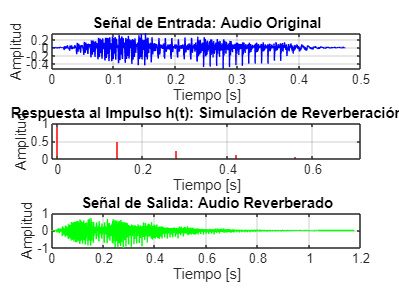

%Lectura del archivo de sonido wav
[audio, fs] = audioread('Hola.wav');
audio = audio(:, 1); 
t_audio = (0:length(audio)-1) / fs; % Eje de tiempo para el audio

sound(audio, fs) 

%Respuesta al impulso para simular reverberación
impulse_gap = round(0.14 * fs); % Espaciado entre impulsos 
num_impulses = 5; % Número de impulsos
h = zeros(1, num_impulses * impulse_gap); % Inicializamos h(t)
for i = 1:num_impulses
    h((i-1)*impulse_gap + 1) = 0.5^(i-1); % Amplitud decreciente a la mitad por impulso
end
t_h = (0:length(h)-1) / fs; % Eje de tiempo para h(t)

%Implementación de la convolucion
len_audio = length(audio);
len_h = length(h);
len_conv = len_audio + len_h - 1;
output = zeros(len_conv, 1); % Inicializamos la señal de salida

% Convolución manual
for n = 1:len_conv
    for k = 1:len_h
        if (n - k + 1 > 0) && (n - k + 1 <= len_audio)
            output(n) = output(n) + h(k) * audio(n - k + 1);
        end
    end
end

%Normalizar y guardar el audio procesado
output = output / max(abs(output)); % Normalización



% Eje de tiempo para la salida
t_output = (0:length(output)-1) / fs;

%Graficar las señales
figure;

% Graficar entrada del audio
subplot(3, 1, 1);
plot(t_audio, audio, 'b');
title('Señal de Entrada: Audio Original');
xlabel('Tiempo [s]');
ylabel('Amplitud');
grid on;

% Graficar respuesta al impulso
subplot(3, 1, 2);
stem(t_h, h, 'r', 'Marker', 'none');
title('Respuesta al Impulso h(t): Simulación de Reverberación');
xlabel('Tiempo [s]');
ylabel('Amplitud');
grid on;

% Graficar señal de salida
subplot(3, 1, 3);
plot(t_output, output, 'g');
title('Señal de Salida: Audio Reverberado');
xlabel('Tiempo [s]');
ylabel('Amplitud');
grid on;


%Reproducir el audio procesado
sound(output, fs); 